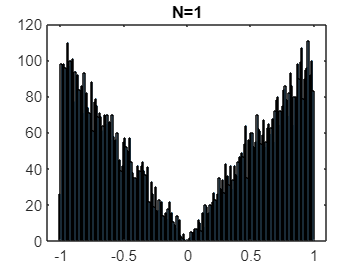

% First we draw histogram for N=1,2,4,..,64
x = zeros(7,10000);
rng(0);
 
N = 2^0;
for j=1:10000
    x(1,j) = AvgDraws(N);
end
histogram(x(1,1:10000),200);
title('N=1')

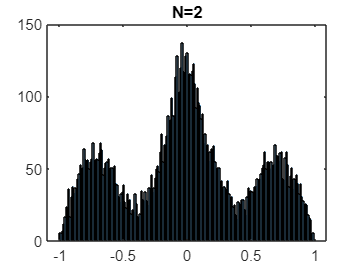


N = 2^1;
for j=1:10000
    x(2,j) = AvgDraws(N);
end
histogram(x(2,1:10000),200);
title('N=2')

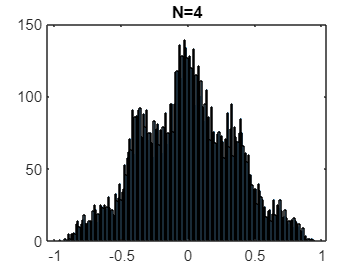


N = 2^2;
for j=1:10000
    x(3,j) = AvgDraws(N);
end
histogram(x(3,1:10000),200);
title('N=4')

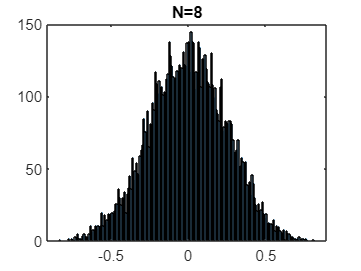


N = 2^3;
for j=1:10000
    x(4,j) = AvgDraws(N);
end
histogram(x(4,1:10000),200);
title('N=8')

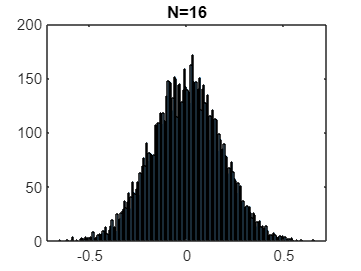


N = 2^4;
for j=1:10000
    x(5,j) = AvgDraws(N);
end
histogram(x(5,1:10000),200);
title('N=16')

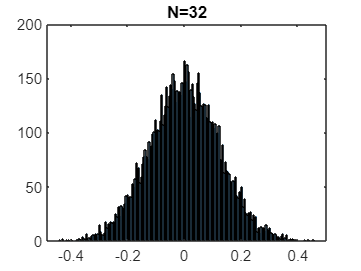


N = 2^5;
for j=1:10000
    x(6,j) = AvgDraws(N);
end
histogram(x(6,1:10000),200);
title('N=32')

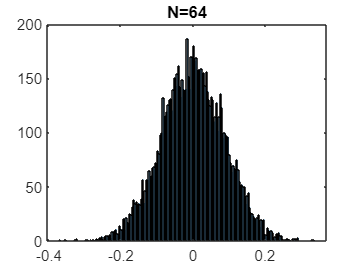


N = 2^6;
for j=1:10000
    x(7,j) = AvgDraws(N);
end
histogram(x(7,1:10000),200);
title('N=64')

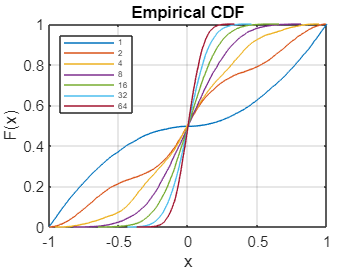



cdfplot(x(1,:));
hold on;
cdfplot(x(2,:));
hold on;
cdfplot(x(3,:));
hold on;
cdfplot(x(4,:));
hold on;
cdfplot(x(5,:));
hold on;
cdfplot(x(6,:));
hold on;
cdfplot(x(7,:));
hold on;

lgd = legend('1','2','4','8','16','32','64');
lgd.Location = "northwest";
lgd.FontSize = 5;